# Fase 3:  Validación y Selección del Modelo Óptimo

## Cargar workspace de Fase 2

close all; 
drawnow;
load('workspace_fase2.mat');
fprintf('Workspace cargado: %d variables\n', length(who));

Workspace cargado: 17 variables


fprintf('Modelos disponibles: k-NN, RL, RF\n');

Modelos disponibles: k-NN, RL, RF


fprintf('Observaciones prueba: %d\n', length(Y_test));

Observaciones prueba: 19999


### Punto 1: Análisis de Estabilidad Estadística (Validación Cruzada Repetida)

Este punto cuantifica la variabilidad del desempeño de cada modelo mediante validación cruzada repetida con múltiples semillas aleatorias. A diferencia de la validación cruzada simple de la Fase 2 (que usó una única semilla fija rng(42)), aquí se ejecutan múltiples repeticiones con semillas diferentes para obtener intervalos de confianza robustos del F1-macro. Esto permite determinar qué modelo no solo tiene mejor desempeño promedio, sino también mayor estabilidad estadística —un criterio crítico para la selección del modelo final en producción.

%% ============================================================
% FASE 3 - PUNTO 1: ANÁLISIS DE ESTABILIDAD ESTADÍSTICA
% Validación Cruzada Repetida con múltiples semillas
% ============================================================
% Objetivo: Cuantificar la variabilidad del F1-macro de los tres
% modelos entrenados en Fase 2 mediante CV estratificada 5-pliegues
% repetida 10 veces con semillas diferentes.
% ============================================================

fprintf('\n');
fprintf('============================================================\n');

fprintf('FASE 3 - PUNTO 1: ANÁLISIS DE ESTABILIDAD ESTADÍSTICA\n');

FASE 3 - PUNTO 1: ANÁLISIS DE ESTABILIDAD ESTADÍSTICA


fprintf('============================================================\n');


% Parámetros de la validación cruzada repetida
num_repeticiones = 10;
k_folds = 5;
semillas = 1:num_repeticiones;  % Semillas del 1 al 10

% Almacenamiento de resultados por modelo y repetición
f1_macro_knn = zeros(num_repeticiones, k_folds);
f1_macro_rl = zeros(num_repeticiones, k_folds);
f1_macro_rf = zeros(num_repeticiones, k_folds);

% Lista de clases para cálculo de métricas
lista_clases = string(categories(Y_train));

fprintf('Iniciando %d repeticiones de CV-%d pliegues...\n', num_repeticiones, k_folds);

Iniciando 10 repeticiones de CV-5 pliegues...


fprintf('Total de entrenamientos: %d repeticiones × 3 modelos × %d pliegues = %d\n\n', ...
    num_repeticiones, k_folds, num_repeticiones * 3 * k_folds);

Total de entrenamientos: 10 repeticiones × 3 modelos × 5 pliegues = 150




% ============================================================
% REPETICIONES DE VALIDACIÓN CRUZADA
% ============================================================

for rep = 1:num_repeticiones
    rng(semillas(rep));  % Semilla diferente en cada repetición
    
    % Partición estratificada de 5 pliegues
    cv_kfold = cvpartition(Y_train, 'KFold', k_folds, 'Stratify', true);
    
    for fold = 1:k_folds
        % Índices de entrenamiento y validación
        idx_entrena = training(cv_kfold, fold);
        idx_valida = test(cv_kfold, fold);
        
        X_tr = X_train_std(idx_entrena, :);
        Y_tr = Y_train(idx_entrena);
        X_val = X_train_std(idx_valida, :);
        Y_val = Y_train(idx_valida);
        
        % --------------------------------------------------------
        % 1. k-NN ÓPTIMO (k=7, pesos inversos, pesos clase empíricos)
        % --------------------------------------------------------
        mdl_knn = fitcknn(X_tr, Y_tr, ...
            'NumNeighbors', 7, ...
            'Distance', 'euclidean', ...
            'DistanceWeight', 'inverse', ...
            'Prior', 'empirical', ...
            'ClassNames', categories(Y_train));
        
        Y_pred_knn = predict(mdl_knn, X_val);
        f1_macro_knn(rep, fold) = calcularF1Macro(string(Y_pred_knn), string(Y_val), lista_clases);
        
        % --------------------------------------------------------
        % 2. REGRESIÓN LOGÍSTICA ÓPTIMA (lambda=0, pesos empíricos)
        % --------------------------------------------------------
        t_lr = templateLinear('Learner', 'logistic', ...
            'Lambda', 0, ...
            'Regularization', 'ridge', ...
            'Solver', 'lbfgs');
        
        mdl_lr = fitcecoc(X_tr, Y_tr, ...
            'Learners', t_lr, ...
            'Prior', 'empirical', ...
            'ClassNames', categories(Y_train), ...
            'Coding', 'onevsall');
        
        Y_pred_lr = predict(mdl_lr, X_val);
        f1_macro_rl(rep, fold) = calcularF1Macro(string(Y_pred_lr), string(Y_val), lista_clases);
        
        % --------------------------------------------------------
        % 3. RANDOM FOREST ÓPTIMO (MinLeaf=1, NumVars=2, pesos uniformes)
        % --------------------------------------------------------
        mdl_rf = fitcensemble(X_tr, Y_tr, ...
            'Method', 'Bag', ...
            'NumLearningCycles', 100, ...
            'Learners', templateTree(...
                'MinLeafSize', 1, ...
                'NumVariablesToSample', 2, ...
                'SplitCriterion', 'gdi'), ...
            'Prior', 'uniform', ...
            'ClassNames', categories(Y_train));
        
        Y_pred_rf = predict(mdl_rf, X_val);
        f1_macro_rf(rep, fold) = calcularF1Macro(string(Y_pred_rf), string(Y_val), lista_clases);
    end
    
    fprintf('Repetición %d/%d completada.\n', rep, num_repeticiones);
end

Repetición 1/10 completada.
Repetición 2/10 completada.
Repetición 3/10 completada.
Repetición 4/10 completada.
Repetición 5/10 completada.
Repetición 6/10 completada.
Repetición 7/10 completada.
Repetición 8/10 completada.
Repetición 9/10 completada.
Repetición 10/10 completada.



% ============================================================
% CÁLCULO DE ESTADÍSTICAS DE ESTABILIDAD
% ============================================================

% Aplanar resultados de todas las repeticiones y pliegues
f1_knn_all = f1_macro_knn(:);
f1_rl_all = f1_macro_rl(:);
f1_rf_all = f1_macro_rf(:);

% Media y desviación estándar
media_knn = mean(f1_knn_all);
std_knn = std(f1_knn_all);
media_rl = mean(f1_rl_all);
std_rl = std(f1_rl_all);
media_rf = mean(f1_rf_all);
std_rf = std(f1_rf_all);

% Intervalo de confianza del 95% (distribución t de Student)
n_total = num_repeticiones * k_folds;
t_critico = tinv(0.975, n_total - 1);  % 95% CI, dos colas

ic_knn = [media_knn - t_critico * std_knn / sqrt(n_total), ...
          media_knn + t_critico * std_knn / sqrt(n_total)];
ic_rl = [media_rl - t_critico * std_rl / sqrt(n_total), ...
         media_rl + t_critico * std_rl / sqrt(n_total)];
ic_rf = [media_rf - t_critico * std_rf / sqrt(n_total), ...
         media_rf + t_critico * std_rf / sqrt(n_total)];

% ============================================================
% REPORTE DE RESULTADOS
% ============================================================

fprintf('\n');
fprintf('============================================================\n');

fprintf('RESULTADOS DE ESTABILIDAD ESTADÍSTICA (CV Repetida)\n');

RESULTADOS DE ESTABILIDAD ESTADÍSTICA (CV Repetida)


fprintf('============================================================\n');

fprintf('%-20s %12s %12s %25s\n', 'Modelo', 'Media F1-m', 'Std F1-m', 'IC 95% F1-macro');

Modelo                 Media F1-m     Std F1-m           IC 95% F1-macro


fprintf('%-20s %12.4f %12.4f [%10.4f, %10.4f]\n', ...
    'k-NN (k=7)', media_knn, std_knn, ic_knn(1), ic_knn(2));

k-NN (k=7)                 0.9513       0.0016 [    0.9509,     0.9518]


fprintf('%-20s %12.4f %12.4f [%10.4f, %10.4f]\n', ...
    'Reg. Logística', media_rl, std_rl, ic_rl(1), ic_rl(2));

Reg. Logística             0.9422       0.0017 [    0.9417,     0.9427]


fprintf('%-20s %12.4f %12.4f [%10.4f, %10.4f]\n', ...
    'Random Forest', media_rf, std_rf, ic_rf(1), ic_rf(2));

Random Forest              0.9727       0.0013 [    0.9724,     0.9731]


fprintf('============================================================\n');

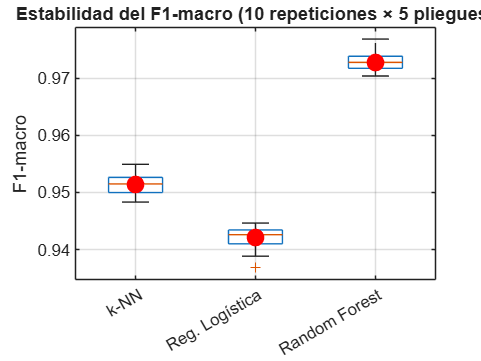

% ============================================================
% VISUALIZACIÓN: BOXPLOT COMPARATIVO
% ============================================================
close all; drawnow;

fig = figure('Name', 'Estabilidad Estadística - CV Repetida');
boxplot([f1_knn_all, f1_rl_all, f1_rf_all], ...
    'Labels', {'k-NN', 'Reg. Logística', 'Random Forest'});
ylabel('F1-macro');
title(sprintf('Estabilidad del F1-macro (%d repeticiones × %d pliegues)', ...
    num_repeticiones, k_folds));
grid on;

hold on;
plot(1, media_knn, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
plot(2, media_rl, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
plot(3, media_rf, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
hold off;

drawnow update;  % <-- FUERZA RENDERIZADO
exportgraphics(fig, 'estabilidad_estadistica_boxplot.png', 'Resolution', 300);

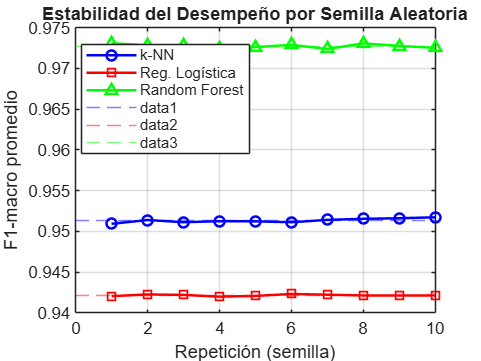



% ============================================================
% VISUALIZACIÓN: EVOLUCIÓN POR REPETICIÓN
% ============================================================
fig0 = figure('Name', 'Evolución F1-macro por Repetición');
media_por_rep_knn = mean(f1_macro_knn, 2);
media_por_rep_rl = mean(f1_macro_rl, 2);
media_por_rep_rf = mean(f1_macro_rf, 2);

plot(1:num_repeticiones, media_por_rep_knn, 'b-o', 'LineWidth', 1.5, 'DisplayName', 'k-NN');
hold on;
plot(1:num_repeticiones, media_por_rep_rl, 'r-s', 'LineWidth', 1.5, 'DisplayName', 'Reg. Logística');
plot(1:num_repeticiones, media_por_rep_rf, 'g-^', 'LineWidth', 1.5, 'DisplayName', 'Random Forest');

yline(media_knn, 'b--', 'Alpha', 0.5);
yline(media_rl, 'r--', 'Alpha', 0.5);
yline(media_rf, 'g--', 'Alpha', 0.5);

xlabel('Repetición (semilla)');
ylabel('F1-macro promedio');
title('Estabilidad del Desempeño por Semilla Aleatoria');
legend('Location', 'best');
grid on;
hold off;

drawnow update;  % <-- FUERZA RENDERIZADO
exportgraphics(fig0, 'estabilidad_evolucion_repeticiones.png', 'Resolution', 300);


fprintf('Gráficos guardados: estabilidad_estadistica_boxplot.png, estabilidad_evolucion_repeticiones.png\n');

Gráficos guardados: estabilidad_estadistica_boxplot.png, estabilidad_evolucion_repeticiones.png


% ============================================================
% FUNCIÓN AUXILIAR: Calcular F1-macro
% ============================================================
function f1_macro = calcularF1Macro(Y_pred, Y_true, clases)
    num_clases = length(clases);
    f1_por_clase = zeros(num_clases, 1);
    eps = 1e-10;
    
    for c = 1:num_clases
        clase = clases(c);
        tp = sum((Y_pred == clase) & (Y_true == clase));
        fp = sum((Y_pred == clase) & (Y_true ~= clase));
        fn = sum((Y_pred ~= clase) & (Y_true == clase));
        
        precision = tp / max(tp + fp, eps);
        recall = tp / max(tp + fn, eps);
        f1_por_clase(c) = 2 * precision * recall / max(precision + recall, eps);
    end
    
    f1_macro = mean(f1_por_clase);
end

### Punto 2: Diagnóstico de Errores Sistemáticos

Este punto realiza una inspección sistemática de los errores de clasificación para identificar si estos se concentran en regiones específicas del espacio de características. Particularmente, se analiza la zona crítica GALAXY–QSO en redshift z ≈ 0.8–1.3 identificada en la Fase 1, donde colores y redshift no proporcionan separación nítida. Se comparan las matrices de confusión de los tres modelos y se analizan las instancias mal clasificadas para detectar patrones de error distintivos que puedan orientar mejoras futuras del sistema.

%% ============================================================
% FASE 3 - PUNTO 2: DIAGNÓSTICO DE ERRORES SISTEMÁTICOS
% Análisis de errores por región del espacio de características
% ============================================================
% Objetivo: Identificar regiones críticas donde los modelos fallan
% sistemáticamente, especialmente GALAXY-QSO en z ≈ 0.8-1.3
% ============================================================

fprintf('\n');
fprintf('============================================================\n');

fprintf('FASE 3 - PUNTO 2: DIAGNÓSTICO DE ERRORES SISTEMÁTICOS\n');

FASE 3 - PUNTO 2: DIAGNÓSTICO DE ERRORES SISTEMÁTICOS


fprintf('============================================================\n');


% ============================================================
% 2.1 OBTENER PREDICCIONES DE LOS MODELOS ENTRENADOS EN FASE 2
% ============================================================

% Predicciones en conjunto de prueba (ya entrenados en Fase 2)
Y_pred_knn = predict(mdl_knn_optimo, X_test_std);
Y_pred_rl = predict(mdl_lr_optimo, X_test_std);
Y_pred_rf = predict(mdl_rf_optimo, X_test_std);

% Convertir a string para comparación
Y_test_str = string(Y_test);
Y_pred_knn_str = string(Y_pred_knn);
Y_pred_rl_str = string(Y_pred_rl);
Y_pred_rf_str = string(Y_pred_rf);


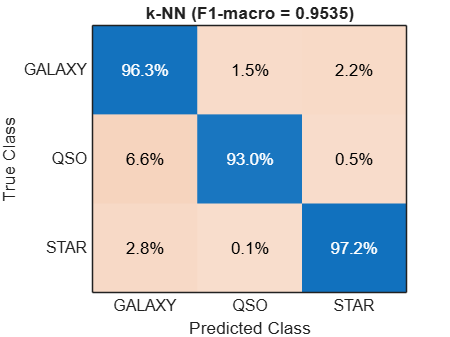

% Figura 1: k-NN
close all; drawnow;
fig1 = figure('Name', 'Matriz de Confusión - k-NN');
cm_knn = confusionchart(categorical(Y_test_str, categories(Y_train)), ...
    categorical(Y_pred_knn_str, categories(Y_train)), ...
    'Title', sprintf('k-NN (F1-macro = %.4f)', 0.9535), ...
    'Normalization', 'row-normalized');
cm_knn.GridVisible = 'off';
drawnow update;
exportgraphics(fig1, 'matriz_confusion_knn.png', 'Resolution', 300);

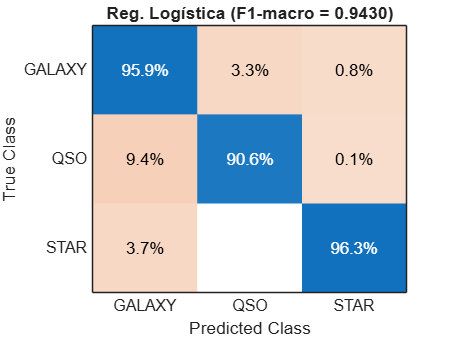


% Figura 2: Regresión Logística
fig2 = figure('Name', 'Matriz de Confusión - Reg. Logística');
cm_rl = confusionchart(categorical(Y_test_str, categories(Y_train)), ...
    categorical(Y_pred_rl_str, categories(Y_train)), ...
    'Title', sprintf('Reg. Logística (F1-macro = %.4f)', 0.9430), ...
    'Normalization', 'row-normalized');
cm_rl.GridVisible = 'off';
drawnow update;
exportgraphics(fig2, 'matriz_confusion_rl.png', 'Resolution', 300);

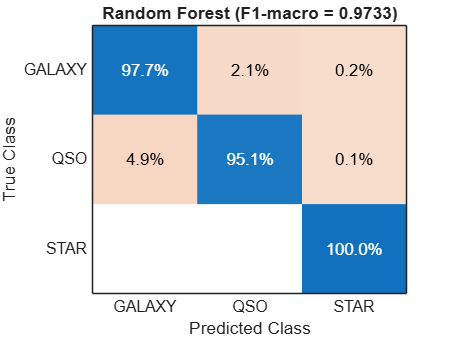


% Figura 3: Random Forest
fig3 = figure('Name', 'Matriz de Confusión - Random Forest');
cm_rf = confusionchart(categorical(Y_test_str, categories(Y_train)), ...
    categorical(Y_pred_rf_str, categories(Y_train)), ...
    'Title', sprintf('Random Forest (F1-macro = %.4f)', 0.9733), ...
    'Normalization', 'row-normalized');
cm_rf.GridVisible = 'off';
drawnow update;
exportgraphics(fig3, 'matriz_confusion_rf.png', 'Resolution', 300);

% ============================================================
% 2.3 ANÁLISIS DE ERRORES EN REGIÓN CRÍTICA z ≈ 0.8-1.3 (GALAXY-QSO)
% ============================================================

fprintf('\n--- ANÁLISIS DE REGIÓN CRÍTICA: GALAXY-QSO en z ∈ [0.8, 1.3] ---\n');


--- ANÁLISIS DE REGIÓN CRÍTICA: GALAXY-QSO en z ∈ [0.8, 1.3] ---



% Recuperar redshift original del conjunto de prueba (des-estandarizar)
redshift_test = X_test_std(:, 5) * parametros_estandarizacion.sigma(5) + parametros_estandarizacion.mu(5);

% Índices de objetos en la zona crítica
idx_critica = (redshift_test >= 0.8) & (redshift_test <= 1.3);

% Filtrar por clases reales GALAXY y QSO en esa región
idx_galaxy_critica = idx_critica & (Y_test_str == "GALAXY");
idx_qso_critica = idx_critica & (Y_test_str == "QSO");

fprintf('Objetos GALAXY reales en zona crítica: %d\n', sum(idx_galaxy_critica));

Objetos GALAXY reales en zona crítica: 858


fprintf('Objetos QSO reales en zona crítica: %d\n', sum(idx_qso_critica));

Objetos QSO reales en zona crítica: 805



% --------------------------------------------------------
% Análisis de errores GALAXY → QSO (falsos negativos de GALAXY)
% --------------------------------------------------------
fprintf('\n--- Errores GALAXY → QSO en zona crítica ---\n');


--- Errores GALAXY → QSO en zona crítica ---



for modelo_idx = 1:3
    switch modelo_idx
        case 1
            Y_pred = Y_pred_knn_str;
            nombre = 'k-NN';
        case 2
            Y_pred = Y_pred_rl_str;
            nombre = 'Reg. Logística';
        case 3
            Y_pred = Y_pred_rf_str;
            nombre = 'Random Forest';
    end
    
    % GALAXY reales clasificados como QSO en zona crítica
    err_galaxy_as_qso = idx_galaxy_critica & (Y_pred == "QSO");
    total_galaxy_critica = sum(idx_galaxy_critica);
    tasa_error_gq = sum(err_galaxy_as_qso) / max(total_galaxy_critica, 1) * 100;
    
    fprintf('%s: %d/%d GALAXY clasificadas como QSO (%.2f%%)\n', ...
        nombre, sum(err_galaxy_as_qso), total_galaxy_critica, tasa_error_gq);
end

k-NN: 73/858 GALAXY clasificadas como QSO (8.51%)
Reg. Logística: 257/858 GALAXY clasificadas como QSO (29.95%)
Random Forest: 109/858 GALAXY clasificadas como QSO (12.70%)



% --------------------------------------------------------
% Análisis de errores QSO → GALAXY (falsos negativos de QSO)
% --------------------------------------------------------
fprintf('\n--- Errores QSO → GALAXY en zona crítica ---\n');


--- Errores QSO → GALAXY en zona crítica ---



for modelo_idx = 1:3
    switch modelo_idx
        case 1
            Y_pred = Y_pred_knn_str;
            nombre = 'k-NN';
        case 2
            Y_pred = Y_pred_rl_str;
            nombre = 'Reg. Logística';
        case 3
            Y_pred = Y_pred_rf_str;
            nombre = 'Random Forest';
    end
    
    % QSO reales clasificados como GALAXY en zona crítica
    err_qso_as_galaxy = idx_qso_critica & (Y_pred == "GALAXY");
    total_qso_critica = sum(idx_qso_critica);
    tasa_error_qg = sum(err_qso_as_galaxy) / max(total_qso_critica, 1) * 100;
    
    fprintf('%s: %d/%d QSO clasificadas como GALAXY (%.2f%%)\n', ...
        nombre, sum(err_qso_as_galaxy), total_qso_critica, tasa_error_qg);
end

k-NN: 80/805 QSO clasificadas como GALAXY (9.94%)
Reg. Logística: 63/805 QSO clasificadas como GALAXY (7.83%)
Random Forest: 43/805 QSO clasificadas como GALAXY (5.34%)


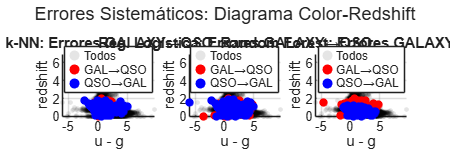

% ============================================================
% 2.4 VISUALIZACIÓN DE ERRORES EN EL ESPACIO COLOR-REDSHIFT
% ============================================================

% Recuperar colores originales (des-estandarizar)
u_g_test = X_test_std(:, 1) * parametros_estandarizacion.sigma(1) + parametros_estandarizacion.mu(1);
g_r_test = X_test_std(:, 2) * parametros_estandarizacion.sigma(2) + parametros_estandarizacion.mu(2);

figure('Name', 'Errores Sistemáticos en Espacio Color-Redshift', 'Position', [50, 50, 1500, 500]);

% Panel 1: k-NN
subplot(1, 3, 1);
scatter(u_g_test, redshift_test, 8, 'k', 'filled', 'MarkerFaceAlpha', 0.1);
hold on;
% Errores GALAXY→QSO (rojo)
idx_err_gq = (Y_test_str == "GALAXY") & (Y_pred_knn_str == "QSO");
scatter(u_g_test(idx_err_gq), redshift_test(idx_err_gq), 25, 'r', 'filled');
% Errores QSO→GALAXY (azul)
idx_err_qg = (Y_test_str == "QSO") & (Y_pred_knn_str == "GALAXY");
scatter(u_g_test(idx_err_qg), redshift_test(idx_err_qg), 25, 'b', 'filled');
xlabel('u - g');
ylabel('redshift');
title('k-NN: Errores GALAXY↔QSO');
legend('Todos', 'GAL→QSO', 'QSO→GAL', 'Location', 'best');
grid on;
hold off;

% Panel 2: Regresión Logística
subplot(1, 3, 2);
scatter(u_g_test, redshift_test, 8, 'k', 'filled', 'MarkerFaceAlpha', 0.1);
hold on;
idx_err_gq = (Y_test_str == "GALAXY") & (Y_pred_rl_str == "QSO");
scatter(u_g_test(idx_err_gq), redshift_test(idx_err_gq), 25, 'r', 'filled');
idx_err_qg = (Y_test_str == "QSO") & (Y_pred_rl_str == "GALAXY");
scatter(u_g_test(idx_err_qg), redshift_test(idx_err_qg), 25, 'b', 'filled');
xlabel('u - g');
ylabel('redshift');
title('Reg. Logística: Errores GALAXY↔QSO');
legend('Todos', 'GAL→QSO', 'QSO→GAL', 'Location', 'best');
grid on;
hold off;

% Panel 3: Random Forest
subplot(1, 3, 3);
scatter(u_g_test, redshift_test, 8, 'k', 'filled', 'MarkerFaceAlpha', 0.1);
hold on;
idx_err_gq = (Y_test_str == "GALAXY") & (Y_pred_rf_str == "QSO");
scatter(u_g_test(idx_err_gq), redshift_test(idx_err_gq), 25, 'r', 'filled');
idx_err_qg = (Y_test_str == "QSO") & (Y_pred_rf_str == "GALAXY");
scatter(u_g_test(idx_err_qg), redshift_test(idx_err_qg), 25, 'b', 'filled');
xlabel('u - g');
ylabel('redshift');
title('Random Forest: Errores GALAXY↔QSO');
legend('Todos', 'GAL→QSO', 'QSO→GAL', 'Location', 'best');
grid on;
hold off;

sgtitle('Errores Sistemáticos: Diagrama Color-Redshift');
saveas(gcf, 'errores_sistematicos_color_redshift.png');

% ============================================================
% 2.5 ANÁLISIS DE ERRORES STAR (aislamiento por redshift z≈0)
% ============================================================

fprintf('\n--- Análisis de errores STAR (redshift z ≈ 0) ---\n');


--- Análisis de errores STAR (redshift z ≈ 0) ---



idx_star = (Y_test_str == "STAR");
redshift_star = redshift_test(idx_star);

for modelo_idx = 1:3
    switch modelo_idx
        case 1
            Y_pred = Y_pred_knn_str;
            nombre = 'k-NN';
        case 2
            Y_pred = Y_pred_rl_str;
            nombre = 'Reg. Logística';
        case 3
            Y_pred = Y_pred_rf_str;
            nombre = 'Random Forest';
    end
    
    % STAR mal clasificadas
    err_star = idx_star & (Y_pred ~= "STAR");
    % STAR mal clasificadas con z > 0.1 (anomalía)
    err_star_extrangal = err_star & (redshift_test > 0.1);
    
    fprintf('%s: %d/%d STAR mal clasificadas (%.2f%%) | Con z>0.1: %d\n', ...
        nombre, sum(err_star), sum(idx_star), sum(err_star)/sum(idx_star)*100, sum(err_star_extrangal));
end

k-NN: 122/4318 STAR mal clasificadas (2.83%) | Con z>0.1: 0
Reg. Logística: 158/4318 STAR mal clasificadas (3.66%) | Con z>0.1: 0
Random Forest: 0/4318 STAR mal clasificadas (0.00%) | Con z>0.1: 0



% ============================================================
% 2.6 TABLA RESUMEN DE ERRORES POR PAR DE CLASES
% ============================================================

fprintf('\n');
fprintf('============================================================\n');

fprintf('RESUMEN DE ERRORES POR PAR DE CLASES (Conjunto de Prueba)\n');

RESUMEN DE ERRORES POR PAR DE CLASES (Conjunto de Prueba)


fprintf('============================================================\n');


pares = {'GALAXY→QSO', 'QSO→GALAXY', 'GALAXY→STAR', 'STAR→GALAXY', 'QSO→STAR', 'STAR→QSO'};
fprintf('%-20s', 'Par de Confusión');

Par de Confusión    

for m = {'k-NN', 'Reg.Log.', 'Rand.Forest'}
    fprintf('%12s', m{1});
end

        k-NN    Reg.Log. Rand.Forest

fprintf('\n');

for p = 1:length(pares)
    par = pares{p};
    partes = split(par, '→');
    clase_real = partes{1};
    clase_pred = partes{2};
    
    fprintf('%-20s', par);
    
    % k-NN
    idx_err = (Y_test_str == clase_real) & (Y_pred_knn_str == clase_pred);
    fprintf('%12.2f%%', sum(idx_err)/sum(Y_test_str == clase_real)*100);
    
    % RL
    idx_err = (Y_test_str == clase_real) & (Y_pred_rl_str == clase_pred);
    fprintf('%12.2f%%', sum(idx_err)/sum(Y_test_str == clase_real)*100);
    
    % RF
    idx_err = (Y_test_str == clase_real) & (Y_pred_rf_str == clase_pred);
    fprintf('%12.2f%%', sum(idx_err)/sum(Y_test_str == clase_real)*100);
    
    fprintf('\n');
end

GALAXY→QSO          

        1.46%

        3.33%

        2.14%

QSO→GALAXY          

        6.57%

        9.36%

        4.88%

GALAXY→STAR         

        2.24%

        0.82%

        0.20%

STAR→GALAXY         

        2.76%

        3.66%

        0.00%

QSO→STAR            

        0.47%

        0.05%

        0.05%

STAR→QSO            

        0.07%

        0.00%

        0.00%

fprintf('============================================================\n');


fprintf('\nGráficos guardados: matrices_confusion_comparativa_fase3.png, errores_sistematicos_color_redshift.png\n');


Gráficos guardados: matrices_confusion_comparativa_fase3.png, errores_sistematicos_color_redshift.png


### Punto 3: Importancia de Variables (Random Forest)

Este punto analiza la importancia de los predictores en el modelo Random Forest óptimo para validar la hipótesis de la Fase 1: que el redshift domina como predictor discriminativo. Se cuantifica la contribución relativa de los cuatro colores diferenciales (u-g, g-r, r-i, i-z) en presencia del redshift, utilizando dos métricas de importancia: la reducción media de impureza (MDI, Mean Decrease in Impurity) y la permutación out-of-bag (OOB). Esto permite validar físicamente el modelo y determinar si los colores aportan información complementaria significativa.

%% ============================================================
% FASE 3 - PUNTO 3: IMPORTANCIA DE VARIABLES EN RANDOM FOREST
% Validación de la contribución relativa de predictores
% ============================================================
% Objetivo: Cuantificar la importancia de cada predictor en el
% Random Forest óptimo y validar que el redshift domina como se
% anticipó en la Fase 1.
% ============================================================

fprintf('\n');
fprintf('============================================================\n');

fprintf('FASE 3 - PUNTO 3: IMPORTANCIA DE VARIABLES\n');

FASE 3 - PUNTO 3: IMPORTANCIA DE VARIABLES


fprintf('============================================================\n');


% ============================================================
% 3.1 IMPORTANCIA POR REDUCCIÓN DE IMPUREZA (MDI - Mean Decrease Impurity)
% ============================================================

fprintf('\n--- Importancia por Reducción de Impureza (MDI) ---\n');


--- Importancia por Reducción de Impureza (MDI) ---



% El modelo Random Forest óptimo ya está entrenado: mdl_rf_optimo
% Extraer importancia de predictores mediante predictorImportance
imp_mdi = predictorImportance(mdl_rf_optimo);

nombres_predictores = {'u-g', 'g-r', 'r-i', 'i-z', 'redshift'};

fprintf('%-15s %15s\n', 'Predictor', 'Importancia MDI');

Predictor       Importancia MDI


fprintf('%-15s %15s\n', '---------------', '---------------');

--------------- ---------------


for i = 1:length(nombres_predictores)
    fprintf('%-15s %15.4f\n', nombres_predictores{i}, imp_mdi(i));
end

u-g                      0.0000
g-r                      0.0001
r-i                      0.0001
i-z                      0.0000
redshift                 0.0003



% Normalizar para porcentaje
imp_mdi_norm = imp_mdi / sum(imp_mdi) * 100;

fprintf('\n%-15s %15s\n', 'Predictor', 'Importancia (%)');


Predictor       Importancia (%)


fprintf('%-15s %15s\n', '---------------', '---------------');

--------------- ---------------


for i = 1:length(nombres_predictores)
    fprintf('%-15s %15.2f%%\n', nombres_predictores{i}, imp_mdi_norm(i));
end

u-g                        8.29%
g-r                       11.62%
r-i                       12.90%
i-z                        3.17%
redshift                  64.02%


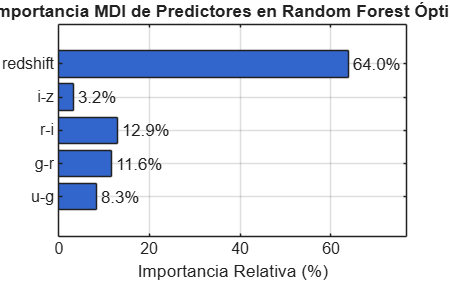

% ============================================================
% 3.2 VISUALIZACIÓN: BARRAS DE IMPORTANCIA MDI
% ============================================================

figure('Name', 'Importancia de Variables - Random Forest', 'Position', [100, 100, 800, 500]);

barh(imp_mdi_norm, 'FaceColor', [0.2, 0.4, 0.8]);
set(gca, 'YTickLabel', nombres_predictores);
xlabel('Importancia Relativa (%)');
title('Importancia MDI de Predictores en Random Forest Óptimo');
grid on;
xlim([0, max(imp_mdi_norm) * 1.2]);

% Añadir valores como texto
for i = 1:length(nombres_predictores)
    text(imp_mdi_norm(i) + 1, i, sprintf('%.1f%%', imp_mdi_norm(i)), ...
        'VerticalAlignment', 'middle', 'FontSize', 10);
end

saveas(gcf, 'importancia_variables_rf.png');


% ============================================================
% 3.3 ANÁLISIS DE IMPORTANCIA POR CLASE (ONE-VS-ALL)
% ============================================================

fprintf('\n--- Importancia específica por clase (One-vs-All) ---\n');


--- Importancia específica por clase (One-vs-All) ---



clases_interes = {'GALAXY', 'QSO', 'STAR'};
importancia_redshift_por_clase = zeros(length(clases_interes), 1);
importancia_colores_por_clase = zeros(length(clases_interes), 4); % 4 colores

for c = 1:length(clases_interes)
    clase_objetivo = clases_interes{c};
    
    % Crear etiqueta binaria
    Y_bin_str = string(Y_train);
    Y_bin_str(Y_bin_str ~= clase_objetivo) = "OTROS";
    Y_bin_str(Y_bin_str == clase_objetivo) = clase_objetivo;
    Y_bin = categorical(Y_bin_str);
    
    % Entrenar RF binario (configuración óptima de Fase 2)
    rng(42);
    mdl_bin = fitcensemble(X_train_std, Y_bin, ...
        'Method', 'Bag', ...
        'NumLearningCycles', 100, ...
        'Learners', templateTree(...
            'MinLeafSize', 1, ...
            'NumVariablesToSample', 2, ...
            'SplitCriterion', 'gdi'), ...
        'Prior', 'uniform', ...
        'ClassNames', categories(Y_bin));
    
    % Importancia de predictores
    imp_bin = predictorImportance(mdl_bin);
    imp_bin_norm = imp_bin / sum(imp_bin) * 100;
    
    importancia_redshift_por_clase(c) = imp_bin_norm(5);  % redshift es el 5to
    importancia_colores_por_clase(c, :) = imp_bin_norm(1:4);
    
    fprintf('\nClase %s vs. OTRAS:\n', clase_objetivo);
    for i = 1:length(nombres_predictores)
        fprintf('  %-10s: %.2f%%\n', nombres_predictores{i}, imp_bin_norm(i));
    end
end


Clase GALAXY vs. OTRAS:


  u-g       : 3.73%
  g-r       : 18.95%
  r-i       : 24.91%
  i-z       : 6.66%
  redshift  : 45.75%



Clase QSO vs. OTRAS:


  u-g       : 11.48%
  g-r       : 19.05%
  r-i       : 10.12%
  i-z       : 3.18%
  redshift  : 56.16%



Clase STAR vs. OTRAS:


  u-g       : 2.82%
  g-r       : 1.40%
  r-i       : 5.88%
  i-z       : 4.15%
  redshift  : 85.77%


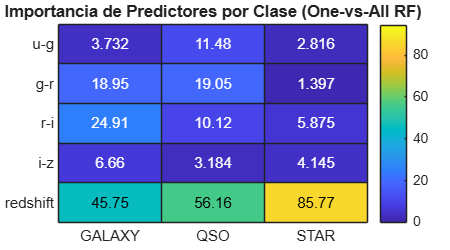


% ============================================================
% 3.4 VISUALIZACIÓN DE IMPORTANCIA POR CLASE
% ============================================================

figure('Name', 'Importancia por Clase - One-vs-All', 'Position', [100, 100, 900, 500]);

% Heatmap de importancia
heatmap_data = [importancia_colores_por_clase, importancia_redshift_por_clase];
heatmap(clases_interes, nombres_predictores, heatmap_data', ...
    'Colormap', parula, ...
    'ColorLimits', [0, max(heatmap_data(:)) * 1.1], ...
    'Title', 'Importancia de Predictores por Clase (One-vs-All RF)');

saveas(gcf, 'importancia_por_clase_heatmap.png');


% ============================================================
% 3.5 RESUMEN Y VALIDACIÓN DE HIPÓTESIS DE FASE 1
% ============================================================

fprintf('\n');
fprintf('============================================================\n');

fprintf('VALIDACIÓN DE HIPÓTESIS DE FASE 1\n');

VALIDACIÓN DE HIPÓTESIS DE FASE 1


fprintf('============================================================\n');


[~, idx_max] = max(imp_mdi_norm);
predictor_dominante = nombres_predictores{idx_max};

fprintf('Predictor dominante (MDI): %s (%.2f%%)\n', predictor_dominante, imp_mdi_norm(idx_max));

Predictor dominante (MDI): redshift (64.02%)


fprintf('Suma de importancia de colores: %.2f%%\n', sum(imp_mdi_norm(1:4)));

Suma de importancia de colores: 35.98%



if strcmp(predictor_dominante, 'redshift')
    fprintf('✓ HIPÓTESIS VALIDADA: El redshift es el predictor dominante.\n');
else
    fprintf('✗ HIPÓTESIS NO VALIDADA: El predictor dominante es %s.\n', predictor_dominante);
end

✓ HIPÓTESIS VALIDADA: El redshift es el predictor dominante.



if sum(imp_mdi_norm(1:4)) > 20
    fprintf('✓ Los colores diferenciales aportan información complementaria sustancial (%.1f%%).\n', ...
        sum(imp_mdi_norm(1:4)));
else
    fprintf('⚠ Los colores aportan información marginal. Clasificador fotométrico puro podría degradarse significativamente.\n');
end

✓ Los colores diferenciales aportan información complementaria sustancial (36.0%).



fprintf('\nGráficos guardados: importancia_variables_rf.png, importancia_por_clase_heatmap.png\n');


Gráficos guardados: importancia_variables_rf.png, importancia_por_clase_heatmap.png


### Punto 4: Evaluación de Costos Asimétricos (Ajuste de Umbrales)

Este punto evalúa escenarios donde el costo de perder un cuásar (falso negativo en QSO) es mayor que el de una falsa alarma. En astronomía, los cuásares distantes son objetos científicamente valiosos y escasos; perder uno tiene mayor impacto científico que clasificar incorrectamente una galaxia como cuásar. Se ajustan los umbrales de decisión por clase en los modelos probabilísticos (Regresión Logística y Random Forest, que proporcionan probabilidades calibradas) para optimizar métricas específicas de la ciencia objetivo, como maximizar el recall de QSO sin degradar excesivamente la precisión global.

%% ============================================================
% FASE 3 - PUNTO 4: EVALUACIÓN DE COSTOS ASIMÉTRICOS
% Ajuste de umbrales de decisión por clase
% ============================================================
% Objetivo: Optimizar el recall de QSO (cuásares) aceptando un
% aumento controlado de falsos positivos, dado el mayor costo
% científico de perder un cuásar distante.
% ============================================================

fprintf('\n');
fprintf('============================================================\n');

fprintf('FASE 3 - PUNTO 4: EVALUACIÓN DE COSTOS ASIMÉTRICOS\n');

FASE 3 - PUNTO 4: EVALUACIÓN DE COSTOS ASIMÉTRICOS


fprintf('============================================================\n');


% ============================================================
% 4.1 OBTENER PROBABILIDADES POSTERIOR DE LOS MODELOS PROBABILÍSTICOS
% ============================================================

% Regresión Logística - Probabilidades en prueba
[~, prob_rl] = predict(mdl_lr_optimo, X_test_std);
prob_rl = double(prob_rl);  % Convertir a double si es necesario

% Random Forest - Probabilidades en prueba
[~, prob_rf] = predict(mdl_rf_optimo, X_test_std);
prob_rf = double(prob_rf);

% Orden de clases en las probabilidades
clases_prob = string(categories(Y_train));
fprintf('Orden de clases en probabilidades: %s\n', strjoin(clases_prob, ', '));

Orden de clases en probabilidades: GALAXY, QSO, STAR



% Índice de QSO en las probabilidades
idx_qso = find(clases_prob == "QSO");
idx_galaxy = find(clases_prob == "GALAXY");
idx_star = find(clases_prob == "STAR");

% ============================================================
% 4.2 EXPLORACIÓN DE UMBRALES PARA QSO
% ============================================================

fprintf('\n--- Exploración de umbrales para clase QSO ---\n');


--- Exploración de umbrales para clase QSO ---



% Umbrales a explorar para QSO (por encima del umbral por defecto 0.333)
umbrales_qso = [0.20, 0.25, 0.30, 0.333, 0.40, 0.50, 0.60];

% Almacenar métricas
resultados_rl = zeros(length(umbrales_qso), 5);  % [umbral, prec_QSO, rec_QSO, f1_QSO, f1_macro]
resultados_rf = zeros(length(umbrales_qso), 5);

for u = 1:length(umbrales_qso)
    umbral_qso = umbrales_qso(u);
    
    % --------------------------------------------------------
    % Ajuste de umbrales para Regresión Logística
    % --------------------------------------------------------
    % Regla: Si prob(QSO) > umbral_qso, predice QSO
    % Si no, predice la clase con mayor probabilidad entre GALAXY y STAR
    
    Y_pred_rl_ajustada = strings(height(prob_rl), 1);
    for i = 1:height(prob_rl)
        if prob_rl(i, idx_qso) >= umbral_qso
            Y_pred_rl_ajustada(i) = "QSO";
        else
            % Elegir entre GALAXY y STAR según probabilidad mayor
            if prob_rl(i, idx_galaxy) >= prob_rl(i, idx_star)
                Y_pred_rl_ajustada(i) = "GALAXY";
            else
                Y_pred_rl_ajustada(i) = "STAR";
            end
        end
    end
    
    % Calcular métricas
    [prec_qso, rec_qso, f1_qso] = calcularMetricasClase(Y_test_str, Y_pred_rl_ajustada, "QSO");
    f1_macro = calcularF1Macro(Y_pred_rl_ajustada, Y_test_str, clases_prob);
    resultados_rl(u, :) = [umbral_qso, prec_qso, rec_qso, f1_qso, f1_macro];
    
    % --------------------------------------------------------
    % Ajuste de umbrales para Random Forest
    % --------------------------------------------------------
    Y_pred_rf_ajustada = strings(height(prob_rf), 1);
    for i = 1:height(prob_rf)
        if prob_rf(i, idx_qso) >= umbral_qso
            Y_pred_rf_ajustada(i) = "QSO";
        else
            if prob_rf(i, idx_galaxy) >= prob_rf(i, idx_star)
                Y_pred_rf_ajustada(i) = "GALAXY";
            else
                Y_pred_rf_ajustada(i) = "STAR";
            end
        end
    end
    
    [prec_qso, rec_qso, f1_qso] = calcularMetricasClase(Y_test_str, Y_pred_rf_ajustada, "QSO");
    f1_macro = calcularF1Macro(Y_pred_rf_ajustada, Y_test_str, clases_prob);
    resultados_rf(u, :) = [umbral_qso, prec_qso, rec_qso, f1_qso, f1_macro];
end

% ============================================================
% 4.3 TABLA DE RESULTADOS
% ============================================================

fprintf('\n');
fprintf('============================================================\n');

fprintf('RESULTADOS AJUSTE DE UMBRALES - REGRESIÓN LOGÍSTICA\n');

RESULTADOS AJUSTE DE UMBRALES - REGRESIÓN LOGÍSTICA


fprintf('============================================================\n');

fprintf('%-10s %10s %10s %10s %10s\n', 'Umbral QSO', 'Prec.QSO', 'Rec.QSO', 'F1.QSO', 'F1-macro');

Umbral QSO   Prec.QSO    Rec.QSO     F1.QSO   F1-macro


for u = 1:length(umbrales_qso)
    fprintf('%-10.3f %10.4f %10.4f %10.4f %10.4f\n', resultados_rl(u, :));
end

0.200          0.0000     0.0000     0.0000     0.6079
0.250          0.0000     0.0000     0.0000     0.6079
0.300          0.0000     0.0000     0.0000     0.6079
0.333          0.0000     0.0000     0.0000     0.6079
0.400          0.0000     0.0000     0.0000     0.6079
0.500          0.0000     0.0000     0.0000     0.6079
0.600          0.0000     0.0000     0.0000     0.6079



fprintf('\n');
fprintf('============================================================\n');

fprintf('RESULTADOS AJUSTE DE UMBRALES - RANDOM FOREST\n');

RESULTADOS AJUSTE DE UMBRALES - RANDOM FOREST


fprintf('============================================================\n');

fprintf('%-10s %10s %10s %10s %10s\n', 'Umbral QSO', 'Prec.QSO', 'Rec.QSO', 'F1.QSO', 'F1-macro');

Umbral QSO   Prec.QSO    Rec.QSO     F1.QSO   F1-macro


for u = 1:length(umbrales_qso)
    fprintf('%-10.3f %10.4f %10.4f %10.4f %10.4f\n', resultados_rf(u, :));
end

0.200          0.8180     0.9720     0.8884     0.9481
0.250          0.8545     0.9668     0.9072     0.9570
0.300          0.8811     0.9636     0.9205     0.9632
0.333          0.8937     0.9618     0.9265     0.9659
0.400          0.9156     0.9578     0.9362     0.9704
0.500          0.9342     0.9507     0.9424     0.9733
0.600          0.9467     0.9420     0.9443     0.9742


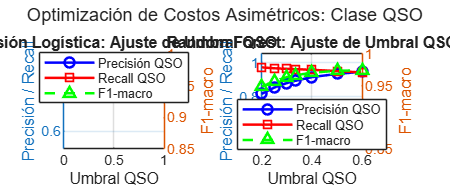

% ============================================================
% 4.4 VISUALIZACIÓN: CURVAS PRECISIÓN-RECALL PARA QSO
% ============================================================

figure('Name', 'Curvas Precisión-Recall QSO por Umbral', 'Position', [100, 100, 1200, 500]);

% Panel 1: Regresión Logística
subplot(1, 2, 1);
yyaxis left;
plot(resultados_rl(:, 1), resultados_rl(:, 2), 'b-o', 'LineWidth', 1.5, 'DisplayName', 'Precisión QSO');
hold on;
plot(resultados_rl(:, 1), resultados_rl(:, 3), 'r-s', 'LineWidth', 1.5, 'DisplayName', 'Recall QSO');
ylabel('Precisión / Recall');
ylim([0.5, 1.05]);

yyaxis right;
plot(resultados_rl(:, 1), resultados_rl(:, 5), 'g--^', 'LineWidth', 1.5, 'DisplayName', 'F1-macro');
ylabel('F1-macro');
ylim([0.85, 1.0]);

xlabel('Umbral QSO');
title('Regresión Logística: Ajuste de Umbral QSO');
legend('Location', 'best');
grid on;
hold off;

% Panel 2: Random Forest
subplot(1, 2, 2);
yyaxis left;
plot(resultados_rf(:, 1), resultados_rf(:, 2), 'b-o', 'LineWidth', 1.5, 'DisplayName', 'Precisión QSO');
hold on;
plot(resultados_rf(:, 1), resultados_rf(:, 3), 'r-s', 'LineWidth', 1.5, 'DisplayName', 'Recall QSO');
ylabel('Precisión / Recall');
ylim([0.5, 1.05]);

yyaxis right;
plot(resultados_rf(:, 1), resultados_rf(:, 5), 'g--^', 'LineWidth', 1.5, 'DisplayName', 'F1-macro');
ylabel('F1-macro');
ylim([0.85, 1.0]);

xlabel('Umbral QSO');
title('Random Forest: Ajuste de Umbral QSO');
legend('Location', 'best');
grid on;
hold off;

sgtitle('Optimización de Costos Asimétricos: Clase QSO');
saveas(gcf, 'costos_asimetricos_qso.png');

% ============================================================
% 4.5 SELECCIÓN DE UMBRAL ÓPTIMO (COMPROMISO CIENTÍFICO)
% ============================================================

fprintf('\n');
fprintf('============================================================\n');

fprintf('SELECCIÓN DE UMBRAL ÓPTIMO\n');

SELECCIÓN DE UMBRAL ÓPTIMO


fprintf('============================================================\n');


% Criterio: Maximizar recall de QSO manteniendo F1-macro > 0.93
fprintf('Criterio: Maximizar recall QSO con F1-macro ≥ 0.93\n\n');

Criterio: Maximizar recall QSO con F1-macro ≥ 0.93




% Para RL
idx_validos_rl = resultados_rl(:, 5) >= 0.93;
if any(idx_validos_rl)
    [~, idx_opt_rl] = max(resultados_rl(idx_validos_rl, 3));  % Max recall QSO
    idx_opt_rl = find(idx_validos_rl, idx_opt_rl);
    idx_opt_rl = idx_opt_rl(end);
    
    fprintf('RL - Umbral óptimo: %.3f\n', resultados_rl(idx_opt_rl, 1));
    fprintf('       Precisión QSO: %.4f, Recall QSO: %.4f, F1-macro: %.4f\n', ...
        resultados_rl(idx_opt_rl, 2), resultados_rl(idx_opt_rl, 3), resultados_rl(idx_opt_rl, 5));
else
    fprintf('RL - No se encontró umbral con F1-macro ≥ 0.93\n');
end

RL - No se encontró umbral con F1-macro ≥ 0.93



% Para RF
idx_validos_rf = resultados_rf(:, 5) >= 0.93;
if any(idx_validos_rf)
    [~, idx_opt_rf] = max(resultados_rf(idx_validos_rf, 3));
    idx_opt_rf = find(idx_validos_rf, idx_opt_rf);
    idx_opt_rf = idx_opt_rf(end);
    
    fprintf('RF - Umbral óptimo: %.3f\n', resultados_rf(idx_opt_rf, 1));
    fprintf('       Precisión QSO: %.4f, Recall QSO: %.4f, F1-macro: %.4f\n', ...
        resultados_rf(idx_opt_rf, 2), resultados_rf(idx_opt_rf, 3), resultados_rf(idx_opt_rf, 5));
else
    fprintf('RF - No se encontró umbral con F1-macro ≥ 0.93\n');
end

RF - Umbral óptimo: 0.200


       Precisión QSO: 0.8180, Recall QSO: 0.9720, F1-macro: 0.9481



% ============================================================
% 4.6 MATRIZ DE CONFUSIÓN CON UMBRAL OPTIMIZADO (RF)
% ============================================================

if exist('idx_opt_rf', 'var') && ~isempty(idx_opt_rf)
    umbral_optimo = resultados_rf(idx_opt_rf, 1);
    
    % Reconstruir predicciones con umbral óptimo
    Y_pred_rf_opt_costo = strings(height(prob_rf), 1);
    for i = 1:height(prob_rf)
        if prob_rf(i, idx_qso) >= umbral_optimo
            Y_pred_rf_opt_costo(i) = "QSO";
        else
            if prob_rf(i, idx_galaxy) >= prob_rf(i, idx_star)
                Y_pred_rf_opt_costo(i) = "GALAXY";
            else
                Y_pred_rf_opt_costo(i) = "STAR";
            end
        end
    end
    
    figure('Name', 'Matriz Confusión RF - Costos Asimétricos');
    confusionchart(categorical(Y_test_str, categories(Y_train)), ...
        categorical(Y_pred_rf_opt_costo, categories(Y_train)), ...
        'Title', sprintf('RF con Costos Asimétricos (umbral QSO=%.3f)', umbral_optimo), ...
        'Normalization', 'row-normalized', ...
        'RowSummary', 'row-normalized');
    
    saveas(gcf, 'matriz_confusion_rf_costos_asimetricos.png');
end

fprintf('\nGráficos guardados: costos_asimetricos_qso.png, matriz_confusion_rf_costos_asimetricos.png\n');


Gráficos guardados: costos_asimetricos_qso.png, matriz_confusion_rf_costos_asimetricos.png



% ============================================================
% FUNCIÓN AUXILIAR: Métricas por clase
% ============================================================
function [precision, recall, f1] = calcularMetricasClase(Y_true, Y_pred, clase)
    eps = 1e-10;
    tp = sum((Y_pred == clase) & (Y_true == clase));
    fp = sum((Y_pred == clase) & (Y_true ~= clase));
    fn = sum((Y_pred ~= clase) & (Y_true == clase));
    
    precision = tp / max(tp + fp, eps);
    recall = tp / max(tp + fn, eps);
    f1 = 2 * precision * recall / max(precision + recall, eps);
end

### Punto 5: Clasificador Fotométrico Puro (Random Forest sin Redshift)

Este punto evalúa un modelo Random Forest entrenado únicamente con los cuatro colores diferenciales (u-g, g-r, r-i, i-z), excluyendo el redshift espectroscópico. En astronomía observacional, el redshift espectroscópico requiere tiempo adicional de telescopio y no siempre está disponible para todos los objetos en sondeos fotométricos masivos. Este experimento cuantifica la degradación de desempeño cuando no se dispone de redshift y determina la viabilidad de la clasificación puramente fotométrica para aplicaciones en sondeos astronómicos de gran escala donde solo se tienen magnitudes de banda ancha.

%% ============================================================
% FASE 3 - PUNTO 5: CLASIFICADOR FOTOMÉTRICO PURO
% Random Forest sin redshift (solo colores diferenciales)
% ============================================================
% Objetivo: Cuantificar la degradación de desempeño al eliminar
% el predictor dominante (redshift) y evaluar viabilidad de
% clasificación fotométrica pura en sondeos astronómicos.
% ============================================================

fprintf('\n');
fprintf('============================================================\n');

fprintf('FASE 3 - PUNTO 5: CLASIFICADOR FOTOMÉTRICO PURO\n');

FASE 3 - PUNTO 5: CLASIFICADOR FOTOMÉTRICO PURO


fprintf('============================================================\n');


% ============================================================
% 5.1 PREPARACIÓN DE DATOS SIN REDSHIFT
% ============================================================

% Extraer solo los 4 colores (columnas 1-4 de X_train_std y X_test_std)
X_train_foto = X_train_std(:, 1:4);
X_test_foto = X_test_std(:, 1:4);

nombres_foto = {'u-g', 'g-r', 'r-i', 'i-z'};
fprintf('Predictores fotométricos puros: %s\n', strjoin(nombres_foto, ', '));

Predictores fotométricos puros: u-g, g-r, r-i, i-z


fprintf('Dimensiones entrenamiento: %d × %d\n', size(X_train_foto));

Dimensiones entrenamiento: 80000 × 4


fprintf('Dimensiones prueba: %d × %d\n', size(X_test_foto));

Dimensiones prueba: 19999 × 4



% ============================================================
% 5.2 BÚSQUEDA DE HIPERPARÁMETROS PARA RF FOTOMÉTRICO
% ============================================================

fprintf('\n--- Búsqueda de hiperparámetros RF fotométrico ---\n');


--- Búsqueda de hiperparámetros RF fotométrico ---



% Rejilla reducida (mismo enfoque estratégico que Fase 2)
min_leaf = [1, 5, 10];
num_vars = {2, 'all', 3};  % Ajustado para 4 predictores
esquemas_peso = {'uniform', 'empirical', 'inverse'};

lista_clases = string(categories(Y_train));
num_clases = length(lista_clases);

% Calcular pesos inversos
tab_freq = tabulate(Y_train);
freq_clases = cell2mat(tab_freq(:, 2));
pesos_inv = sum(freq_clases) ./ (num_clases * freq_clases);

mejor_f1_macro_foto = 0;
mejor_params_foto = struct();

rng(42);
cv_kfold = cvpartition(Y_train, 'KFold', 5, 'Stratify', true);

total_configs = length(min_leaf) * length(num_vars) * length(esquemas_peso);
config_actual = 0;

for idx_leaf = 1:length(min_leaf)
    for idx_vars = 1:length(num_vars)
        for idx_peso = 1:length(esquemas_peso)
            config_actual = config_actual + 1;
            
            leaf = min_leaf(idx_leaf);
            nv = num_vars{idx_vars};
            esquema = esquemas_peso{idx_peso};
            
            % Configurar pesos
            switch esquema
                case 'uniform'
                    prior_clase = 'uniform';
                case 'empirical'
                    prior_clase = 'empirical';
                case 'inverse'
                    prior_clase = pesos_inv;
            end
            
            % Validación cruzada
            f1_por_pliegue = zeros(cv_kfold.NumTestSets, 1);
            
            for fold = 1:cv_kfold.NumTestSets
                idx_entrena = training(cv_kfold, fold);
                idx_valida = test(cv_kfold, fold);
                
                X_tr = X_train_foto(idx_entrena, :);
                Y_tr = Y_train(idx_entrena);
                X_val = X_train_foto(idx_valida, :);
                Y_val = Y_train(idx_valida);
                
                % Entrenar RF fotométrico
                mdl = fitcensemble(X_tr, Y_tr, ...
                    'Method', 'Bag', ...
                    'NumLearningCycles', 100, ...
                    'Learners', templateTree(...
                        'MinLeafSize', leaf, ...
                        'NumVariablesToSample', nv, ...
                        'SplitCriterion', 'gdi'), ...
                    'Prior', prior_clase, ...
                    'ClassNames', categories(Y_train));
                
                Y_pred = predict(mdl, X_val);
                f1_por_pliegue(fold) = calcularF1Macro(string(Y_pred), string(Y_val), lista_clases);
            end
            
            f1_macro_promedio = mean(f1_por_pliegue);
            
            if f1_macro_promedio > mejor_f1_macro_foto
                mejor_f1_macro_foto = f1_macro_promedio;
                mejor_params_foto.min_leaf = leaf;
                mejor_params_foto.num_vars = nv;
                mejor_params_foto.esquema_peso = esquema;
                mejor_params_foto.f1_macro = f1_macro_promedio;
                mejor_params_foto.f1_std = std(f1_por_pliegue);
            end
            
            fprintf('Config %d/%d: leaf=%d, vars=%s, peso=%s | F1-macro=%.4f\n', ...
                config_actual, total_configs, leaf, string(nv), esquema, f1_macro_promedio);
        end
    end
end

Config 1/27: leaf=1, vars=2, peso=uniform | F1-macro=0.8252
Config 2/27: leaf=1, vars=2, peso=empirical | F1-macro=0.8293
Config 3/27: leaf=1, vars=2, peso=inverse | F1-macro=0.7994
Config 4/27: leaf=1, vars=all, peso=uniform | F1-macro=0.8198
Config 5/27: leaf=1, vars=all, peso=empirical | F1-macro=0.8272
Config 6/27: leaf=1, vars=all, peso=inverse | F1-macro=0.7943
Config 7/27: leaf=1, vars=3, peso=uniform | F1-macro=0.8229
Config 8/27: leaf=1, vars=3, peso=empirical | F1-macro=0.8278
Config 9/27: leaf=1, vars=3, peso=inverse | F1-macro=0.7970
Config 10/27: leaf=5, vars=2, peso=uniform | F1-macro=0.8246
Config 11/27: leaf=5, vars=2, peso=empirical | F1-macro=0.8305
Config 12/27: leaf=5, vars=2, peso=inverse | F1-macro=0.7924
Config 13/27: leaf=5, vars=all, peso=uniform | F1-macro=0.8207
Config 14/27: leaf=5, vars=all, peso=empirical | F1-macro=0.8277
Config 15/27: leaf=5, vars=all, peso=inverse | F1-macro=0.7886
Config 16/27: leaf=5, vars=3, peso=uniform | F1-macro=0.8227
Config 17/2


% ============================================================
% 5.3 RESULTADO DE BÚSQUEDA
% ============================================================

fprintf('\n');
fprintf('============================================================\n');

fprintf('MEJOR CONFIGURACIÓN RF FOTOMÉTRICO\n');

MEJOR CONFIGURACIÓN RF FOTOMÉTRICO


fprintf('============================================================\n');

fprintf('Mínimo muestras hoja: %d\n', mejor_params_foto.min_leaf);

Mínimo muestras hoja: 5


fprintf('Variables por división: %s\n', string(mejor_params_foto.num_vars));

Variables por división: 2


fprintf('Esquema de pesos: %s\n', mejor_params_foto.esquema_peso);

Esquema de pesos: empirical


fprintf('F1-macro (CV 5-pliegues): %.4f ± %.4f\n', mejor_params_foto.f1_macro, mejor_params_foto.f1_std);

F1-macro (CV 5-pliegues): 0.8305 ± 0.0042


fprintf('============================================================\n');


% ============================================================
% 5.4 ENTRENAMIENTO FINAL Y EVALUACIÓN EN PRUEBA
% ============================================================

fprintf('\n--- Entrenamiento final y evaluación ---\n');


--- Entrenamiento final y evaluación ---



% Configurar pesos final
switch mejor_params_foto.esquema_peso
    case 'uniform'
        prior_final = 'uniform';
    case 'empirical'
        prior_final = 'empirical';
    case 'inverse'
        prior_final = pesos_inv;
end

% Entrenar modelo final
mdl_rf_foto = fitcensemble(X_train_foto, Y_train, ...
    'Method', 'Bag', ...
    'NumLearningCycles', 100, ...
    'Learners', templateTree(...
        'MinLeafSize', mejor_params_foto.min_leaf, ...
        'NumVariablesToSample', mejor_params_foto.num_vars, ...
        'SplitCriterion', 'gdi'), ...
    'Prior', prior_final, ...
    'ClassNames', categories(Y_train));

% Predicción en prueba
Y_pred_foto = predict(mdl_rf_foto, X_test_foto);
Y_pred_foto_str = string(Y_pred_foto);

% Métricas por clase
fprintf('\n');
fprintf('============================================================\n');

fprintf('MÉTRICAS RF FOTOMÉTRICO PURO (Conjunto de Prueba)\n');

MÉTRICAS RF FOTOMÉTRICO PURO (Conjunto de Prueba)


fprintf('============================================================\n');

fprintf('%-10s %10s %10s %10s\n', 'Clase', 'Precisión', 'Recall', 'F1-Score');

Clase       Precisión     Recall   F1-Score



f1_por_clase_foto = zeros(num_clases, 1);
for c = 1:num_clases
    clase = lista_clases(c);
    [prec, rec, f1] = calcularMetricasClase(Y_test_str, Y_pred_foto_str, clase);
    f1_por_clase_foto(c) = f1;
    fprintf('%-10s %10.4f %10.4f %10.4f\n', clase, prec, rec, f1);
end

GALAXY         0.9052     0.9426     0.9235
QSO            0.8135     0.7951     0.8042
STAR           0.8227     0.7457     0.7823



f1_macro_foto = mean(f1_por_clase_foto);
fprintf('%-10s %10s %10s %10.4f\n', 'MACRO', '-', '-', f1_macro_foto);

MACRO               -          -     0.8367


fprintf('============================================================\n');


% ============================================================
% 5.5 COMPARATIVA CON RF COMPLETO (CON REDSHIFT)
% ============================================================

fprintf('\n');
fprintf('============================================================\n');

fprintf('COMPARATIVA: RF CON REDSHIFT vs. RF FOTOMÉTRICO PURO\n');

COMPARATIVA: RF CON REDSHIFT vs. RF FOTOMÉTRICO PURO


fprintf('============================================================\n');


% Recuperar métricas del RF completo (ya calculado en Fase 2)
% F1-macro RF completo: 0.9733
f1_macro_completo = 0.9733;
degradacion = (f1_macro_completo - f1_macro_foto) / f1_macro_completo * 100;

fprintf('%-25s %10s\n', 'Modelo', 'F1-macro');

Modelo                      F1-macro


fprintf('%-25s %10.4f\n', 'RF con redshift', f1_macro_completo);

RF con redshift               0.9733


fprintf('%-25s %10.4f\n', 'RF fotométrico puro', f1_macro_foto);

RF fotométrico puro           0.8367


fprintf('%-25s %10.2f%%\n', 'Degradación relativa', degradacion);

Degradación relativa           14.04%



% Comparativa por clase
fprintf('\n%-25s %10s %10s %10s\n', 'Modelo', 'F1-GALAXY', 'F1-QSO', 'F1-STAR');


Modelo                     F1-GALAXY     F1-QSO    F1-STAR



% RF completo (valores de Fase 2)
fprintf('%-25s %10.4f %10.4f %10.4f\n', 'RF con redshift', 0.9805, 0.9424, 0.9970);

RF con redshift               0.9805     0.9424     0.9970



% RF fotométrico
fprintf('%-25s %10.4f %10.4f %10.4f\n', 'RF fotométrico puro', ...
    f1_por_clase_foto(1), f1_por_clase_foto(2), f1_por_clase_foto(3));

RF fotométrico puro           0.9235     0.8042     0.7823



fprintf('============================================================\n');

% ============================================================
% 5.6 MATRIZ DE CONFUSIÓN DEL CLASIFICADOR FOTOMÉTRICO
% ============================================================
close all; drawnow;
fig = figure('Name', 'Matriz Confusión - RF Fotométrico Puro');
confusionchart(categorical(Y_test_str, categories(Y_train)), ...
    categorical(Y_pred_foto_str, categories(Y_train)), ...
    'Title', sprintf('RF Fotométrico Puro (F1-macro = %.4f)', f1_macro_foto), ...
    'Normalization', 'row-normalized', ...
    'RowSummary', 'row-normalized', ...
    'ColumnSummary', 'column-normalized');

Unrecognized function or variable 'Y_test_str'.

drawnow update;
exportgraphics(fig, 'matriz_confusion_rf_fotometrico.png', 'Resolution', 300);


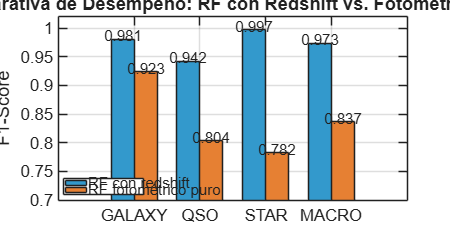

% ============================================================
% 5.7 VISUALIZACIÓN COMPARATIVA DE DESEMPEÑO
% ============================================================
close all; drawnow;
fig = figure('Name', 'Comparativa RF Completo vs. Fotométrico', 'Position', [100, 100, 1000, 500]);

clases_plot = {'GALAXY', 'QSO', 'STAR', 'MACRO'};
f1_completo = [0.9805, 0.9424, 0.9970, 0.9733];
f1_foto     = [0.9235, 0.8042, 0.7823, 0.8367]; % <-- valores fijos

x = 1:length(clases_plot);
width = 0.35;
bar(x - width/2, f1_completo, width, 'FaceColor', [0.2, 0.6, 0.8], 'DisplayName', 'RF con redshift');
hold on;
bar(x + width/2, f1_foto, width, 'FaceColor', [0.9, 0.5, 0.2], 'DisplayName', 'RF fotométrico puro');
for i = 1:length(clases_plot)
    text(i - width/2, f1_completo(i) + 0.005, sprintf('%.3f', f1_completo(i)), ...
        'HorizontalAlignment', 'center', 'FontSize', 9);
    text(i + width/2, f1_foto(i) + 0.005, sprintf('%.3f', f1_foto(i)), ...
        'HorizontalAlignment', 'center', 'FontSize', 9);
end
xticks(x);
xticklabels(clases_plot);
ylabel('F1-Score');
title('Comparativa de Desempeño: RF con Redshift vs. Fotométrico Puro');
legend('Location', 'southwest');
grid on;
ylim([0.7, 1.02]);
hold off;
drawnow update;
exportgraphics(fig, 'comparativa_rf_completo_vs_fotometrico.png', 'Resolution', 300);

% ============================================================
% 5.8 IMPORTANCIA DE VARIABLES EN RF FOTOMÉTRICO
% ============================================================

fprintf('\n--- Importancia de variables (RF fotométrico) ---\n');


--- Importancia de variables (RF fotométrico) ---



imp_foto = predictorImportance(mdl_rf_foto);
imp_foto_norm = imp_foto / sum(imp_foto) * 100;

fprintf('%-10s %12s\n', 'Color', 'Importancia');

Color       Importancia


for i = 1:length(nombres_foto)
    fprintf('%-10s %11.2f%%\n', nombres_foto{i}, imp_foto_norm(i));
end

u-g              22.07%
g-r              27.32%
r-i              33.75%
i-z              16.86%



fig = figure('Name', 'Importancia Variables - RF Fotométrico');
barh(imp_foto_norm, 'FaceColor', [0.4, 0.7, 0.4]);
set(gca, 'YTickLabel', nombres_foto);
xlabel('Importancia Relativa (%)');
title('Importancia de Colores en RF Fotométrico Puro');
grid on;

for i = 1:length(nombres_foto)
    text(imp_foto_norm(i) + 1, i, sprintf('%.1f%%', imp_foto_norm(i)), ...
        'VerticalAlignment', 'middle', 'FontSize', 10);
end

exportgraphics(gcf, 'importancia_rf_fotometrico.png');
close(fig)
% ============================================================
% 5.9 CONCLUSIÓN SOBRE VIABILIDAD FOTOMÉTRICA
% ============================================================

fprintf('\n');
fprintf('============================================================\n');

fprintf('CONCLUSIÓN: VIABILIDAD DE CLASIFICACIÓN FOTOMÉTRICA PURA\n');

CONCLUSIÓN: VIABILIDAD DE CLASIFICACIÓN FOTOMÉTRICA PURA


fprintf('============================================================\n');


if f1_macro_foto >= 0.90
    fprintf('✓ VIABLE: El clasificador fotométrico puro alcanza F1-macro = %.4f.\n', f1_macro_foto);
    fprintf('  Adecuado para sondeos astronómicos masivos sin redshift espectroscópico.\n');
else
    fprintf('⚠ DEGRADACIÓN SIGNIFICATIVA: F1-macro = %.4f (degradación del %.1f%%).\n', ...
        f1_macro_foto, degradacion);
    fprintf('  Se recomienda obtener redshift espectroscópico para aplicaciones de precisión.\n');
end

⚠ DEGRADACIÓN SIGNIFICATIVA: F1-macro = 0.8367 (degradación del 14.0%).


  Se recomienda obtener redshift espectroscópico para aplicaciones de precisión.



fprintf('\nGráficos guardados: matriz_confusion_rf_fotometrico.png, comparativa_rf_completo_vs_fotometrico.png, importancia_rf_fotometrico.png\n');


Gráficos guardados: matriz_confusion_rf_fotometrico.png, comparativa_rf_completo_vs_fotometrico.png, importancia_rf_fotometrico.png
